## **Driver test program to check Clothoids library**

**Test clothoid**

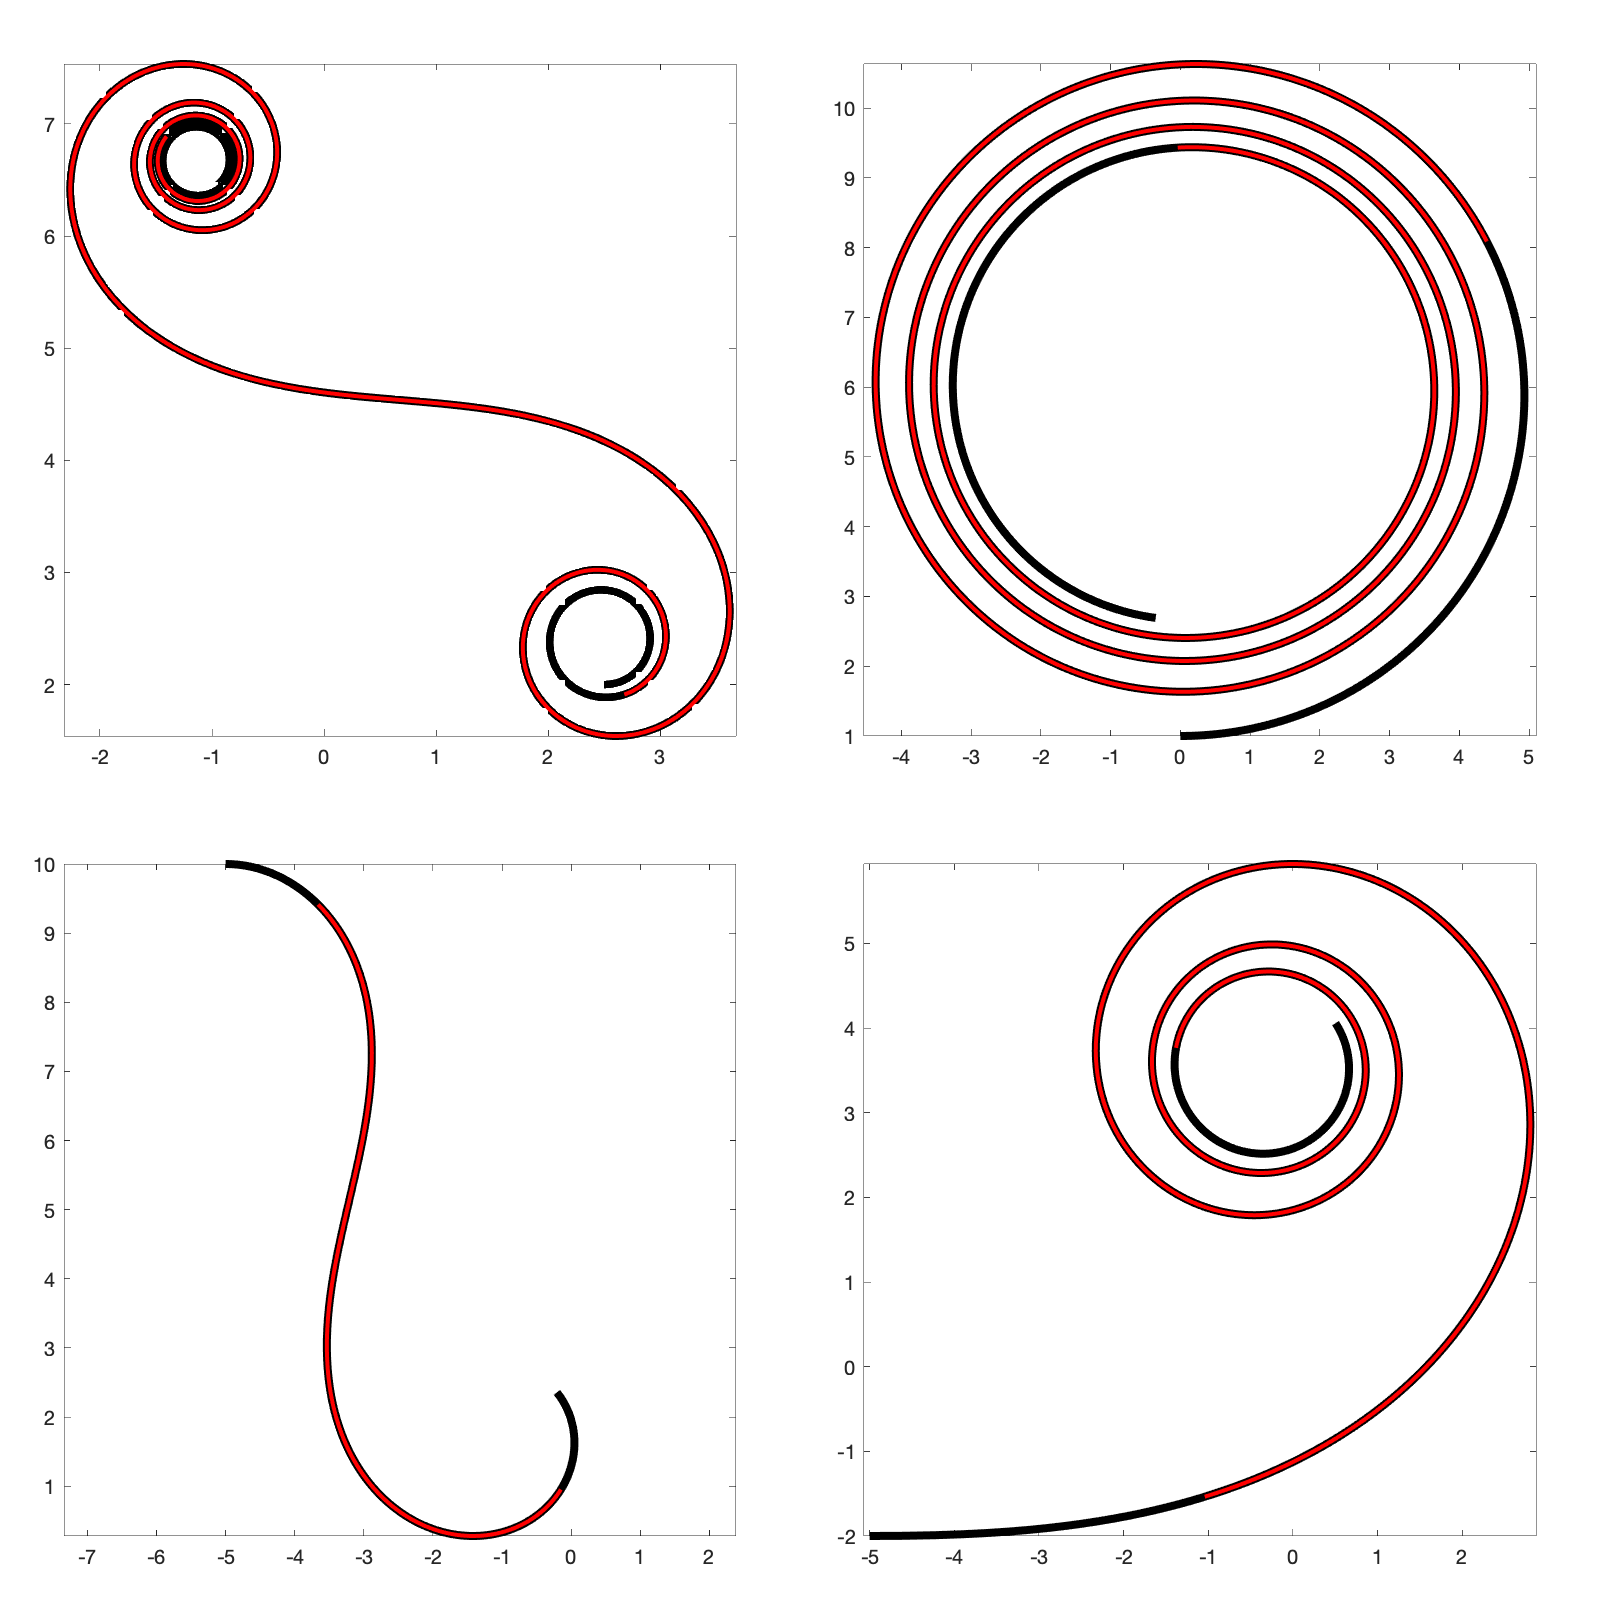

close all;

% check constructors
x0     = [-5,-5,0,2.5];
y0     = [10,-2,1,2];
theta0 = 0;
kappa0 = [-0.6, 0.025, 0.2, 2.5];
dk     = [0.1, 0.025, 0.001, -0.2];
L      = [15,40,100,30];

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end

  L1 = ClothoidCurve( x0(kk), y0(kk), theta0, kappa0(kk), dk(kk), L(kk) );
  L2 = ClothoidCurve();
  L2.copy(L1);
  len = L2.length();
  L2.trim(0.1*len,0.9*len);

  L1.plot( 2, 'Color','black','LineWidth', 4 );
  hold on;
  L2.plot( 2, 'Color','red','LineWidth', 2 );
  axis equal;

  %
  L1.delete();
  L2.delete();
end